Calcular la tasa de error de bit (BER) de un enlace pasivo si la potencia óptica del bit 1 que llega al receptor PIN es P_1 dBm, la relación de extinción (P_1/P_0) es r_e dB, la responsividad del receptor es R, la densidad espectral de ruido de corriente equivalente es N_th y la tasa de bits (BR) es 10 Gbit/s NRZ (ancho de banda eléctrica B_e = 0.7BR).

Suponer que el ruido RIN de la fuente óptica es despreciable.

P_1 = -23; % [dBm] Potencia óptica del bit 1
R = 0.8; % [A/W] LA responsividad del receptor
N_th = 3e-12; % [A/sqrt(Hz)] Densidad espectral de ruido equivalente
r_e = 10; % [dB] Relación de extinción
BR = 10e9; % [Hz] Bit rate
B_e = 0.7 * BR; % [Hz] Ancho de banda eléctrico
e = 1.60217656535e-19;% carga electrica de un electron

## Calcular la tasa de error de bit (BER):

 Asumimos que la función de densidad de probabilidad de todas las fuentes de ruido es gaussiana. Eso quiere decir que tanto para el bit 0 como para el bit 1 el ruido vendrá determinado por un valor medio $v_i$ y una desviación típica $\sigma_i^2$ dentro de su función de probablidad $p_i \left(v\right)$


$$p_i \left(v\right)=\frac{1}{\sqrt{2\pi \sigma_i }}\mathrm{exp}\left\lbrack -\frac{{\left(v-v_i \right)}^2 }{2\sigma_i^2 }\right\rbrack$$


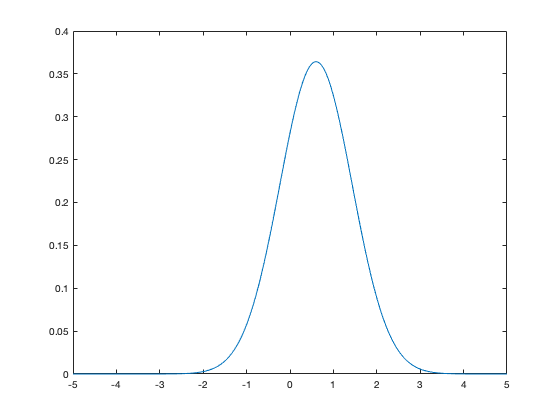

v = -5:0.01:5; % Rango de valores medio
v_i =0.6; % Valor medio a probar
sigma_i = 1.2; % Desviación típica
p = exp(-(v-v_i).^2 / 2 * sigma_i^2) ./ sqrt(2 * pi*sigma_i);
plot(v, p);

La función $p\left(v\right)$ será gaussiana pero será diferente según el bit transmitido sea 0 o 1 (prueba cambiar el valor de $v_i$ entre 0 y 1). También la desviación típica será distinta en cada caso, puesto que, aunque el ruido térmico y el ruido shot de la corriente de oscuridad son constantes e independientes de la señal,** el ruido shot de señal depende del nivel de ésta **(prueba cambiar sigma_i). A mayor nivel de señal (bit 1), mayor será el ruido shot.

Luego, la probabilidad de que, habiéndose enviado un 0 (sitúa $v_i$en 0), v resulte ser mayor que el umbral establecido, que denominaremos $v_u$, es la integral hacia la derecha del umbral de la función anterior. Lo mismo ocurre para el bit 1 (sitúa $v_i$en 1) que la probabilidad de recibir un 0, habiéndose enviado un 1, es la integral hacia la izquierda del umbral de la función gaussiana. Esto se formaliza en el siguiente par de ecuaciones,


$$P\left(1/0\right)=\int_{v_u }^{\infty } p_{\mathrm{min}} \left(v\right)\mathrm{dv}$$
 

y  


$$P\left(0/1\right)=\int_{\infty }^{v_u } p_{\mathrm{max}} \left(v\right)\;\mathrm{dv}$$


 Sustituyendo la función gaussiana en estas dos ecuaciones podemos calcular la probablidad de error total 


$$P_e =\frac{1}{2}\left\lbrack \frac{1}{2}\mathrm{erfc}\left(\frac{v_{\mathrm{max}} -v_u }{\sigma_{\mathrm{max}} \sqrt{2}}\right)+\frac{1}{2}\mathrm{erfc}\left(\frac{v_u -v_{\mathrm{min}} }{\sigma_{\mathrm{min}} \sqrt{2}}\right)\right\rbrack$$


donde introducimos erfc que es la función de error complementaria y permite integrar $e^{-t^2 }$desde un valor cualquiera z, hasta infinito.

 
$$\mathrm{erfc}\left(z\right)=\frac{2}{\sqrt{\pi }}\int_z^{\infty } e^{-t^2 } \mathrm{dt}$$


El valor que interesa es aquel que minimice la probablidad de error total que es el punto de intersección entre 2 gaussianas (la del bit 0 y la del bit 1) es decir $P\left(1/0\right)=P\left(0/1\right)$, lo que conduce a


$$\frac{v_{\mathrm{max}} -v_u }{\sigma_{\mathrm{max}} }=\frac{v_u -v_{\mathrm{min}} }{\sigma_{\mathrm{min}} }=q$$


Donde, despejando $v_u$, tenemos, 


$$v_u =\frac{v_{\mathrm{max}} \sigma_{\mathrm{min}} +v_{\mathrm{min}} \sigma_{\mathrm{max}} }{\sigma_{\mathrm{min}} +\sigma_{\mathrm{max}} }$$


una suma de productos sobre la suma de ambas desviaciones.

Si sustituimos este valor umbral en la ecuación de probabilidad de error total, obtenemos la ecuación que pide el ejercicio, la tasa de error de bit


$$P_e =\frac{1}{2}\mathrm{erfc}\left(\frac{q}{\sqrt{2}}\right)$$


donde $q=\frac{v_{\mathrm{max}} -v_{\mathrm{min}} }{\sigma_{\mathrm{min}} +\sigma_{\mathrm{max}} }$.

Para calcular el valor medio de 1 y de 0 ($v_{\mathrm{max}} y\;v_{\mathrm{min}}$), podemos utilizar la potencia del bit 1 y la responsividad del receptor.

Para un fotodiodo PIN, el valor medio se puede calcular a través de $v_i =R\;P_i$.

v_max = R*10^((P_1-30)/10);
v_min = v_max/10;

Del mismo modo para la desviación tipica, tenemos que de la definición de sensibilidad de receptores ópticos surge una relación entre la desiación, la densidad espectral de ruido equivalente y el ancho de banda, $\sigma_i =\sqrt{N_{\mathrm{th}}^2 \mathrm{Bw}+2e{\;v}_i \;\mathrm{Bw}}\ldotp$

sigma_max = sqrt(N_th^2 *B_e + 2*e*v_max*B_e);
sigma_min = sqrt(N_th^2 *B_e + 2*e*v_min*B_e);
q = (v_max - v_min) / (sigma_max + sigma_min);
BER = erfc(q/sqrt(2))/2

BER = 2.1818e-12